**4.1** From the course website download data matrix D_wdbc.mat. 

load('D_wdbc.mat')

**4.2** Follow Sec. 3.1 above to generate normalized train and test data sets and their labels. 

Dtr = D_wdbc(:,1:285); % traning data
Dte = D_wdbc(:,286:569); % testing data 

% Normalization of the tranning set 
Xtr = zeros(30,285);
m = zeros(1,30);
v = zeros(1,30);
for i = 1:30
 xi = Dtr(i,:);
 m(i) = mean(xi);
 v(i) = sqrt(var(xi));
 Xtr(i,:) = (xi - m(i))/v(i);
end 

% Normalizing the testing set with data from the tranning set
Xte = zeros(30,284);
for i = 1:30
 xi = Dte(i,:);
 Xte(i,:) = (xi - m(i))/v(i);
end 

% Data labels
ytr = Dtr(31,:);
yte = Dte(31,:); 

**4.3** Based on (E4.2) and (E4.3), prepare two MATLAB functions for evaluating the regularized cost function and its gradient, respectively. 

Refer to the functions at the bottom of this script

**4.4** Prepare MATLAB code to minimize ELR(w) in (E4.2) using the GD algorithm (see Sec. 2.3 of the course notes). 

Refer to the functions at the bottom of this script

**4.5 **Set initial point w= **0** and run the code prepared in Item 4.4 to obtain parameters {w,b} for the following settings.

(i) mu= 0 and K=10; 

(ii) mu= 0.1 and K= 10; 

(iii) mu= 0 and K= 30;

 (iv) mu=0.075 and K= 30 .

w = zeros(31,1);
fname = 'f_wdbc';
gname = 'g_wdbc';

%i 
w_i = GD_Lab3(fname,gname, w, [Xtr; ytr], 0, 10);
%ii 
w_ii = GD_Lab3(fname,gname, w, [Xtr; ytr], 0.1, 10);
%iii 
w_iii = GD_Lab3(fname,gname, w, [Xtr; ytr], 0, 30);
%iv 
w_iv = GD_Lab3(fname,gname, w, [Xtr; ytr], 0.075, 30);


**4.6** Use the four solutions obtained in 4.5 above to specify the classifier in (E4.4) and apply it to the 284 test samples prepared in Item 4.2 above. Report the confusion matrix for each case, and comment on the results obtained.

%i 
yp_i = sign((w_i(1:30,:)'*Xte)+w_i(31)); 
confusion_i = confusionmat(yte, yp_i)

confusion_i =    167     4
     3   110


%i 
yp_ii = sign((w_ii(1:30,:)'*Xte)+w_ii(31));
confusion_ii = confusionmat(yte, yp_ii)

confusion_ii =    170     1
     4   109


%i 
yp_iii = sign((w_iii(1:30,:)'*Xte)+w_iii(31));
confusion_iii = confusionmat(yte, yp_iii)

confusion_iii =    169     2
     5   108


%i 
yp_iv = sign((w_iv(1:30,:)'*Xte)+w_iv(31));
confusion_iv = confusionmat(yte, yp_iv)

confusion_iv =    171     0
     4   109

Bonus question

mu_vec_1 = linspace(0, 1, 100); 
accuracy_1 = zeros(size(mu_vec_1));
mu_vec_2 = linspace(1, 100, 100);
accuracy_2 = zeros(size(mu_vec_2));

for i = 1:length(mu_vec_1)
    mu1 = mu_vec_1(i);
    mu2 = mu_vec_2(i);
    
    w_1 = GD_Lab3(fname,gname, w, [Xtr; ytr], mu1, 30);
    w_2 = GD_Lab3(fname,gname, w, [Xtr; ytr], mu2, 30);
    
    yp_1 = sign((w_1(1:30,:)'*Xte)+w_1(31));
    confusion_1 = confusionmat(yte, yp_1);
    accuracy_1(i) = (sum(diag(confusion_1))/284)*100;

    yp_2 = sign((w_2(1:30,:)'*Xte)+w_2(31));
    confusion_2 = confusionmat(yte, yp_2);
    accuracy_2(i) = (sum(diag(confusion_2))/284)*100;  
end 

[~,highest_acc1_idx] = max(accuracy_1);
best_mu1 = mu_vec_1(highest_acc1_idx) 

best_mu1 =    0.070707070707071


[~,highest_acc2_idx] = max(accuracy_2);
best_mu2 = mu_vec_2(highest_acc2_idx)

best_mu2 =      1

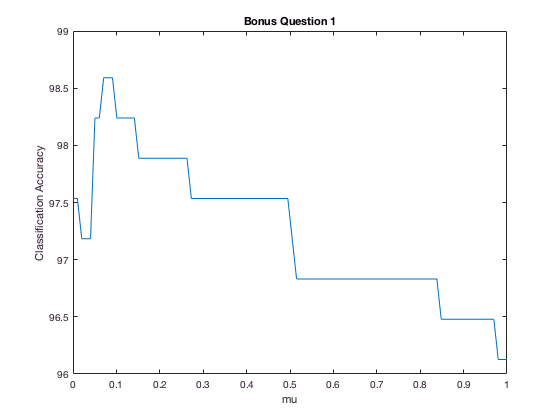


plot(mu_vec_1, accuracy_1)
title('Bonus Question 1') 
xlabel('mu')
ylabel('Classification Accuracy') 

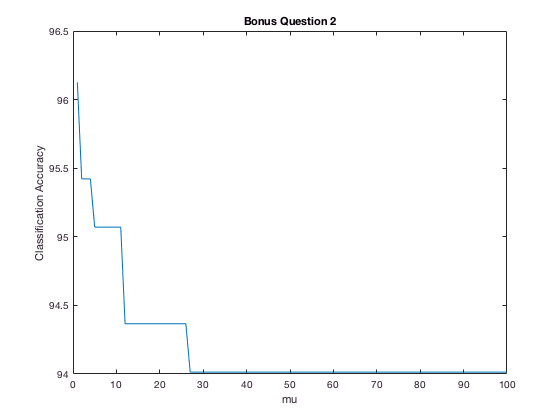


plot(mu_vec_2, accuracy_2)
title('Bonus Question 2') 
xlabel('mu')
ylabel('Classification Accuracy') 

function f = f_wdbc(w,D,mu)
X = D(1:30,:);
y = D(31,:);
P = length(y);
f = 0;
for i = 1:P
    xi = [X(:,i); 1];
    fi = log(1+exp(-y(i)*(w'*xi)));
    f = f + fi;
end
f = f/P + 0.5*mu*norm(w)^2;
end 

function g = g_wdbc(w,D,mu)
X = D(1:30,:);
y = D(31,:);
P = length(y);
g = zeros(31,1);
for i = 1:P
    xi = [X(:,i); 1];
    ei = exp(y(i)*(w'*xi));
    gi = -y(i)*xi/(1+ei);
    g = g + gi;
end
g = g/P + mu*w;
end 

function xs = GD_Lab3(fname,gname,x0,D, mu, K)
format compact
format long
k = 1;
xk = x0;
gk = feval(gname, xk, D, mu);
dk = -gk;
ak = bt_lsearch2019(xk,dk, fname,gname,D, mu);
adk = ak*dk;
while k <= K
  xk = xk + adk;
  gk = feval(gname,xk, D, mu);
  dk = -gk;
  ak = bt_lsearch2019(xk,dk, fname,gname, D, mu);
  adk = ak*dk;
  k = k + 1;
end
xs = xk + adk;
end 

function a = bt_lsearch2019(x,d,fname,gname,p1,p2)
rho = 0.1;
gma = 0.5;
x = x(:);
d = d(:);
a = 1;
xw = x + a*d;
parameterstring ='';
if nargin == 5
   if ischar(p1)
      eval([p1 ';']);
   else
      parameterstring = ',p1';
   end
end
if nargin == 6
   if ischar(p1)
      eval([p1 ';']);
   else
      parameterstring = ',p1';
   end
   if ischar(p2)
      eval([p2 ';']);
   else
      parameterstring = ',p1,p2';
   end
end

eval(['f0 = ' fname '(x' parameterstring ');']);
eval(['g0 = ' gname '(x' parameterstring ');']);
eval(['f1 = ' fname '(xw' parameterstring ');']);

t0 = g0'*d;
f2 = f0 + rho*a*t0;
er = f1 - f2;
while er > 0
     a = gma*a;
     xw = x + a*d;
     eval(['f1 = ' fname '(xw' parameterstring ');']);
     f2 = f0 + rho*a*t0;
     er = f1 - f2;
end
if a < 1e-5
   a = min([1e-5, 0.1/norm(d)]); 
end 
end 